# Perceptron Learning Rule

## Initialization

clear all;clc;
Input=[1 -2 0 -1; 0 -1.5 -0.5 -1.0; -1 1 0.5 -1.0]; 

## Target of input

y=[-1 -1 1];

## Initial weights

Initial_weights=[1 -1 0 0]';

## Learning Rate

eta=0.7;

## Perceptron learing rule

weights=Perceptron(Input,y,Initial_weights,eta)

weights =    -0.4000
    1.8000
         0
    1.4000


## Decision Boundry (Classify points in xy-plane)

## Generate data from gaussian distribution

num_data=20;
Input=randn(num_data,2);

## Output '+1' if x2 >x1

y=ones(num_data,1);

y(Input(:,2)<Input(:,1))=-1;

## Sample data

Sample=[Input(1:5,:) y(1:5,:)]

Sample =    -0.8254   -0.4337    1.0000
    0.6920   -0.2563   -1.0000
    0.0284    1.4738    1.0000
   -0.4295    0.1236    1.0000
    0.7760   -1.2704   -1.0000



Initial_weights=[1 -1]';

## Applying Perceptron Rule

w_Perceptron=Perceptron(Input,y,Initial_weights,eta)

w_Perceptron =    -1.0846
    0.8151


## Plotting Data Points & Decision Boundry

figure
hold on
scatter(Input(y==1,1),Input(y==1,2),'+')
scatter(Input(y==-1,1),Input(y==-1,2),'r')

syms x1 x2
f=w_Perceptron(1)*x1+w_Perceptron(2)*x2

$$f = \frac{1835390317389001\,x_{2}}{2251799813685248}-\frac{4884679719657379\,x_{1}}{4503599627370496}$$

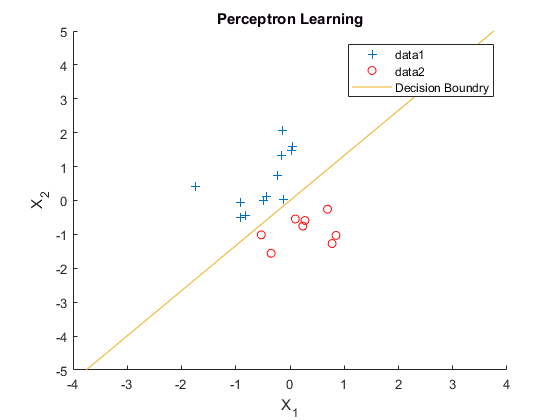

fimplicit(f)
title({'Perceptron Learning'});
xlabel({'X_1'});
ylabel({'X_2'});
legend('data1','data2','Decision Boundry');
hold off